% Workspace initialisation
clc
clear all
close all

N=19407580

N = 19407580


[k,a,b,c,d,wl,wh,ev]=systems_generator(N);

%k,a,b,c,d parameters of the system

%wl minimum gain crossover frequency
%wh maximum gain crossover frequency
%ev maximum velocity error

%section 2

s = tf('s');
g_s = k*(a*s+b)/(s*(s^2+c*s+d)); % transfer function

wc = wl;   % initial gain crossover frequency (lower limit)

% compute the frequency response of the system at the crossover frequency
g_wc = squeeze(freqresp(g_s, wc));
% the magnitude at wc
mag_g_wc = abs(g_wc);

% finding k_p1
k_p1 = 1 / mag_g_wc

k_p1 = 2.5643


% the phase at wc
phase_g_wc = angle(g_wc);
% phase margin
pm = (phase_g_wc + pi)*180/pi 

pm = 0.1905

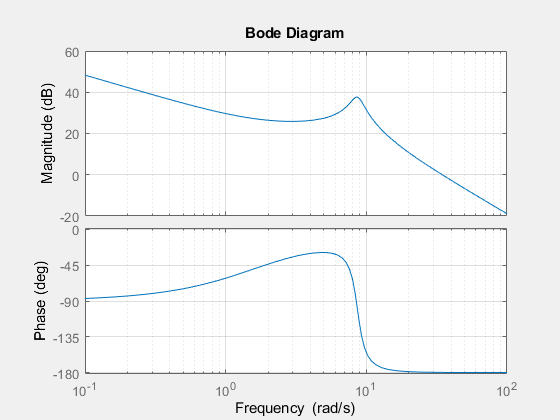


% Examine the frequency response
figure(1); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
bode(k_p1*g_s);
grid on
hold on


% finding k_p2
k_p2 = (1/ev)*(d/(k*b))

k_p2 = 8.5463


% Checking stability margins
allmargin(k_p1*g_s)

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: 0.1904
    PMFrequency: 34.6434
    DelayMargin: 9.5942e-05
    DMFrequency: 34.6434
         Stable: 1


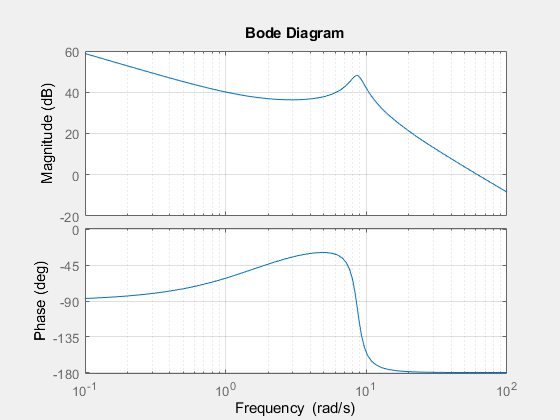


% Examine the frequency response
figure(2); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
bode(k_p2*g_s);
grid on
hold on

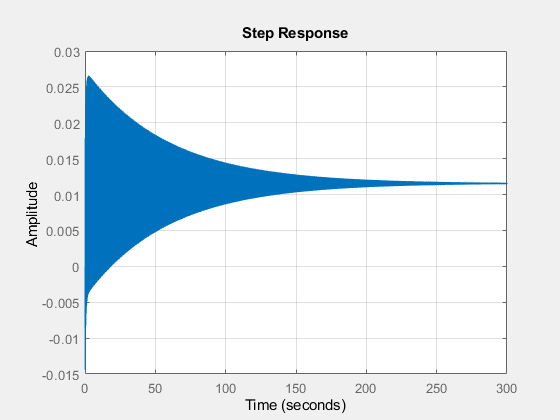


% Visualise the ramp tracking-error
figure(3); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
step(1/s*1/(1+k_p2*g_s));
grid on
hold on


% Checking stability margins
allmargin(k_p2*g_s)

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: 0.0321
    PMFrequency: 61.8467
    DelayMargin: 9.0491e-06
    DMFrequency: 61.8467
         Stable: 1


%section 3
wc = wl %new wc, mid point of wc range, to reduce tracking-error

wc = 34.6410

pm = 70;

k_p = k_p2; %k_p satisfies velocity error

% Compute the frequency response of the system at the crossover frequency wc
p_wc = squeeze(freqresp(g_s, wc));

% Magnitude at wc
mag_p_wc = abs(p_wc);
% Phase at wc
phase_p_wc = angle(p_wc);

% find phi
phi = pm*pi/180 - pi - phase_p_wc

phi = 1.2184

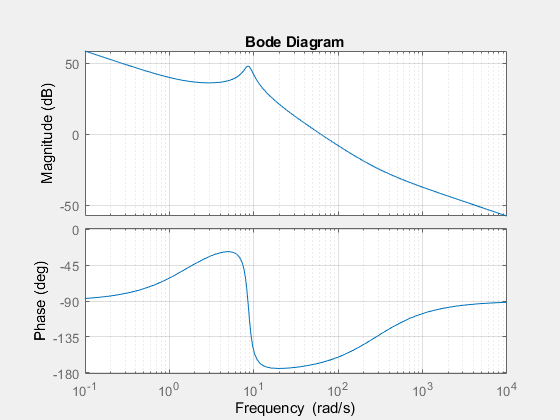

% Compute tz
tz = (mag_p_wc-cos(phi))/(wc*mag_p_wc*sin(phi));
%find alpha
alpha = (mag_p_wc*cos(phi)-1)/mag_p_wc*(mag_p_wc-cos(phi));

% compensator
c_s = k_p*(tz*s+1)/(alpha*tz+1);

% Compute the frequency response of the series of zero and plant at wc
l_s = c_s*g_s;
ls_wc = squeeze(freqresp(c_s*g_s, wc));

% Examine the frequency response of the plant plus the zero of the controller
figure(4); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
bode(l_s);
grid on
hold on


% Checking stability margins
allmargin(l_s)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: 12.5082
    PMFrequency: 62.5909
    DelayMargin: 0.0035
    DMFrequency: 62.5909
         Stable: 1


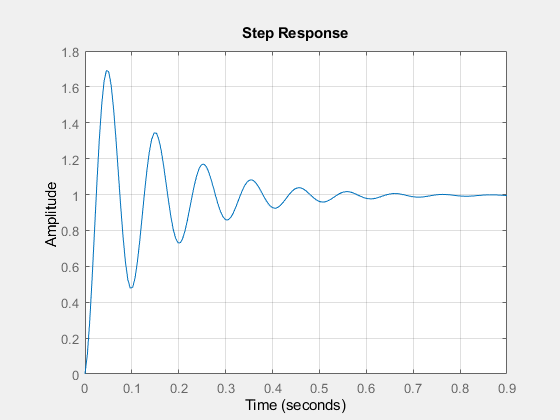


% Closed-loop step response
figure(5); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
step(l_s/(1+l_s));
grid on

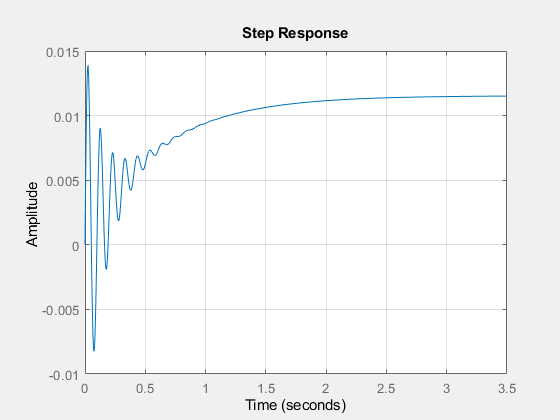


% Visualise the ramp tracking-error
figure(10); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
step(1/s*1/(1+l_s));
grid on
hold on

% section 4

pm = 70; % >55
wc = wl % lower limit of wc

wc = 34.6410

k_p = k_p2; %k_p satisfies velocity error

% Compute the frequency response of the system at the crossover frequency wc
p_wc = squeeze(freqresp(g_s, wc));
% Magnitude at wc
mag_p_wc = abs(p_wc);
% Phase at wc
phase_p_wc = angle(p_wc);

% find phi
phi = pm*pi/180 - pi - phase_p_wc

phi = 1.2184

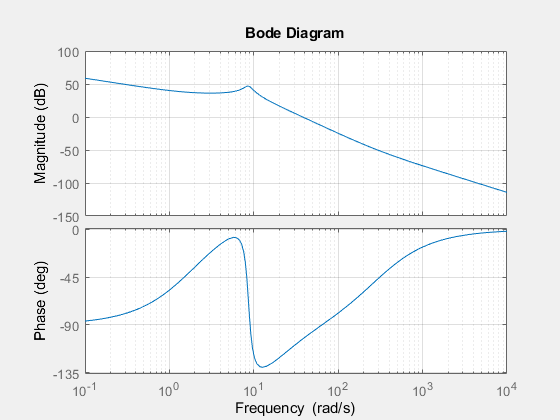

% Compute tz
tz = (mag_p_wc-cos(phi))/(wc*mag_p_wc*sin(phi));
%find alpha
alpha = (mag_p_wc*cos(phi)-1)/mag_p_wc*(mag_p_wc-cos(phi));
% Compute the Tz
Tz = (mag_p_wc*cos(phi)-1)/(wc*mag_p_wc*sin(phi));
%find beta
beta = mag_p_wc*(cos(phi)-mag_p_wc)/(1-mag_p_wc*cos(phi));

% compensator 
c_s = k_p*(tz*s+1)/(alpha*tz+1)*(beta*Tz+1)/(Tz*s+1);

l_s = c_s*g_s;
ls_wc = squeeze(freqresp(c_s*g_s, wc));

% Examine the frequency response of the plant plus the zero of the controller
figure(7); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
bode(l_s);
grid on
hold on


% Checking stability margins
allmargin(l_s)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: 76.6734
    PMFrequency: 37.9466
    DelayMargin: 0.0353
    DMFrequency: 37.9466
         Stable: 0


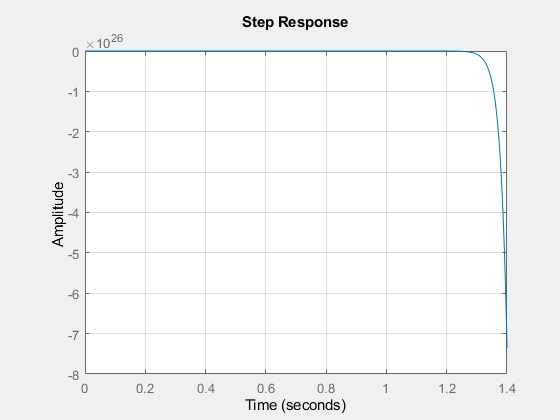


% Closed-loop step response
figure(8); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
step(l_s/(1+l_s));
grid on

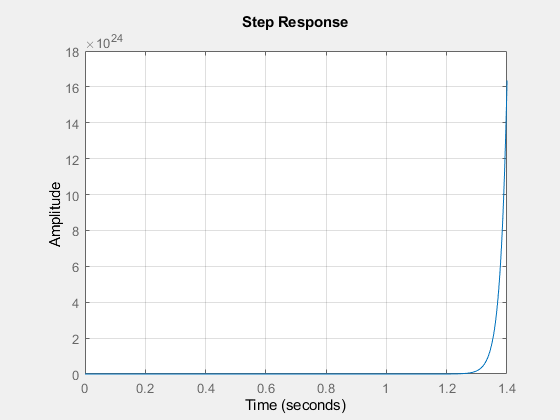


% Visualise the ramp tracking-error
figure(9); set(gcf,'Visible','on'); % Prepare a figure window and set to a visible state
step(1/s*1/(1+l_s));
%legend('G(s)*k_p1: wc=34.6410', 'G(s)*phase-lead controller', 'G(s)*lead-lag controller');
grid on
hold on